# Principle Component Analysis

## Introduction

The file `data8.mat` contains:

- $50$ sample points for the PCA for an easy visualization in the matrix $X_s \in \mathcal M_{50, 2}(\mathbb R)$;

- $5000$ sample images that represents people faces in the matrix $X \in \mathcal M_{5000, 1024}(\mathbb R)$ ($32 \times 32 px$ each).

ToDo

## Data Loading and Visualization

load('data8.mat', "X", "X_s");

#### Visualizing example dataset for PCA

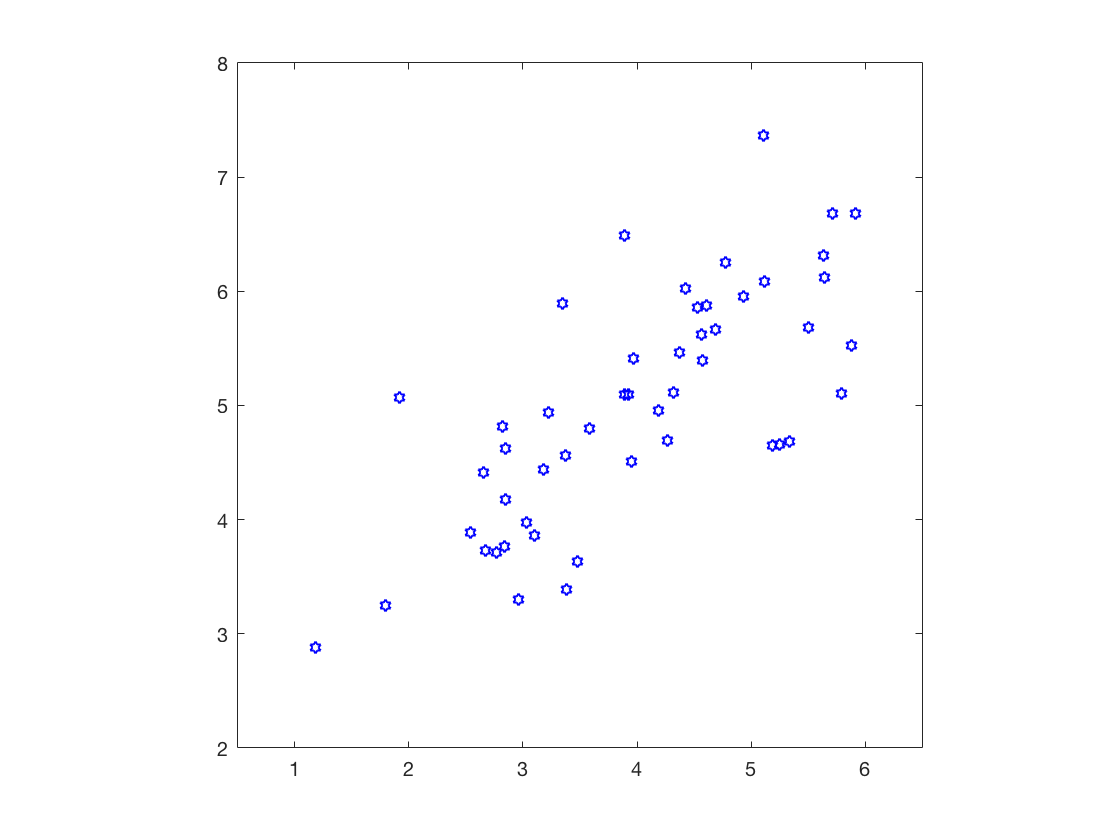

plot(X_s(:, 1), X_s(:, 2), 'bh');
axis([0.5 6.5 2 8]);
axis square;

#### Visualizing Face Data

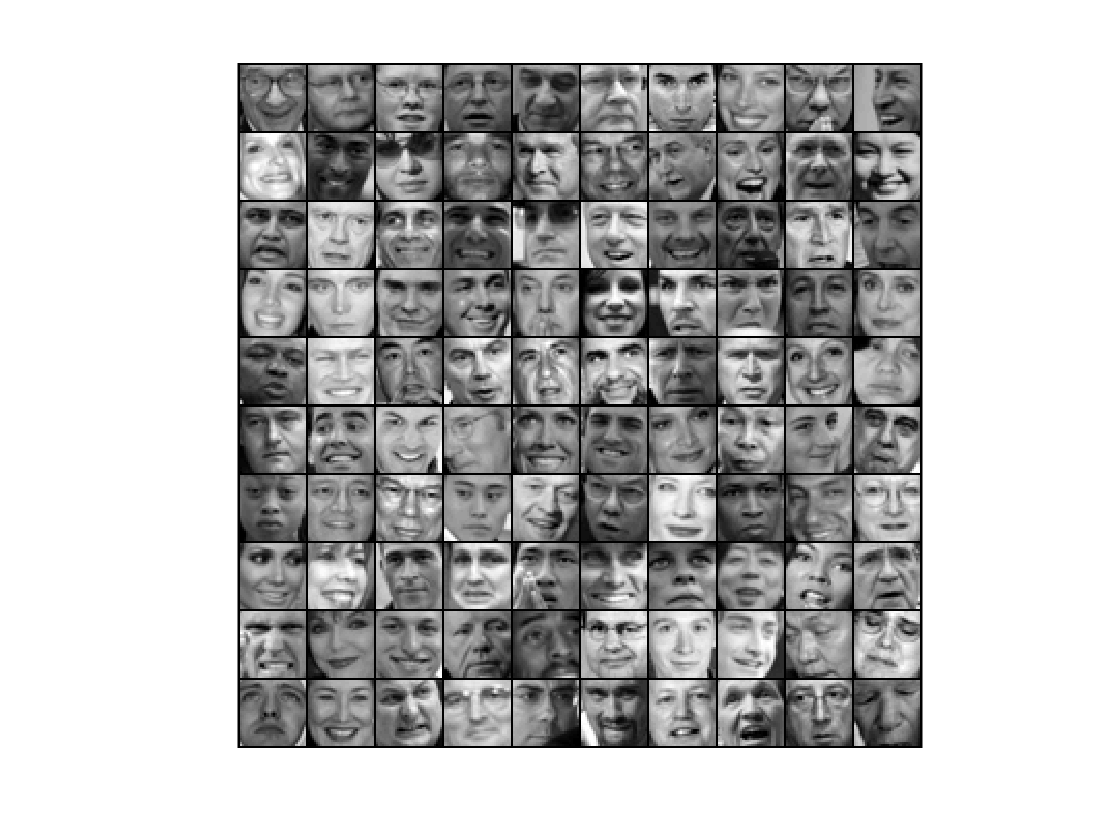

displayData(X(1:100, :));

## Principal Component Analysis

Before running PCA, it is important to first normalize the dataset.

By using *featureNormalize* we also evaluate the mean $\mu$ and the standard deviation $\sigma$.

In particular $\mu$ will be usefull while drawing the Eigenvectors, in order to center them in the mean of the data. The Eigenvectors represent the direction of the maximum variation of the dataset.

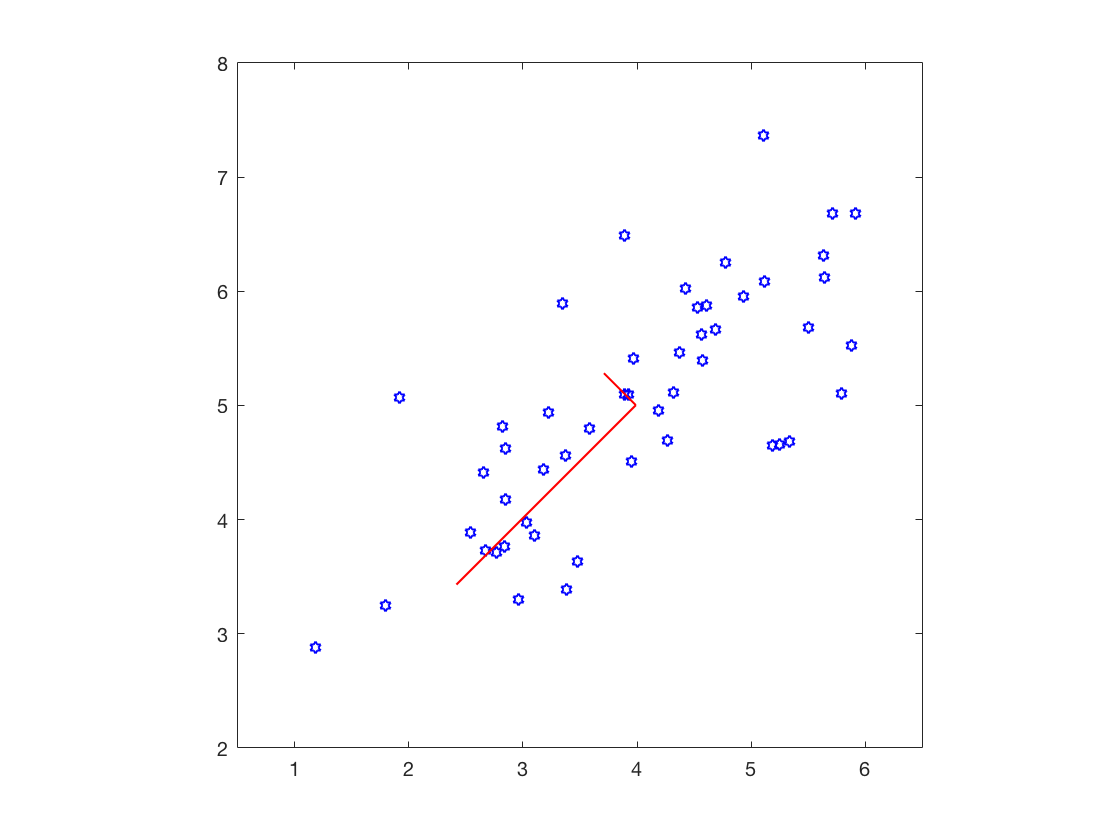

[X_norm, mu, ~] = featureNormalize(X_s);

[U, S] = PCA(X_norm);

[Ur, Sr] = pca(X_norm);
%assert(sum(sum(abs(Ur - U) > 0.001)) == 0);
%assert(sum(sum(abs(Sr - S) > 0.001)) == 0);

plot(X_s(:, 1), X_s(:, 2), 'bh');hold on;
axis([0.5 6.5 2 8]);
axis square;
drawLine(mu, mu + 1.5 * S(1,1) * U(:,1)', 'r-', 'LineWidth', 1);
drawLine(mu, mu + 1.5 * S(2,2) * U(:,2)', 'r-', 'LineWidth', 1);
hold off;


%fprintf('Top eigenvector: \n');
%fprintf(' U(:,1) = %f %f \n', U(1,1), U(2,1));
%fprintf('(you should expect to see -0.707107 -0.707107)\n');